# testing the length calculator


% target = [56.17295863373443 10.191965103149416];
% postion = [56.17260624803534 10.19184708595276];
target = [2 2];
postion = [0 0];

boat_dir = 45;

D = distrance_between_coordinates(postion, target)

D = 2.2544e+05

# Finding the meters per degree constants 

lat_m = latitude_degree_meter(56);
disp(sprintf("lat m = %s", num2str(lat_m)))

lat m = 111218.5834


long_m = longitude_degree_meter;
disp(sprintf("lon m = %s", num2str(long_m)))

lon m = 17717.0472


# Building the logic for the angle calculator 

% target = [56.17295863373443 10.191965103149416];
% postion = [56.17260624803534 10.19184708595276];
target = [2 2];
postion = [0 0];


Localise the target


d_lat = target(1) - postion(1) 

d_lat = 2

d_lon = target(2) - postion(2)

d_lon = 2

FInd the radian angle

angle_radian = atan(d_lon/d_lat)

angle_radian = 0.7854

Convert to degrees

format short
rad_deg_realtion = 360/(2*pi);

target_angle_degrees_tri = angle_radian * rad_deg_realtion

target_angle_degrees_tri = 45

Turn into compass  degrees

target_angle_degres_map = 360-mod((target_angle_degrees_tri-90),360)

target_angle_degres_map = 45

find the inital diffrence between the angles

non_finsihed = boat_dir - target_angle_degres_map;

Figure out if the boat is trying to turn the long way around

if non_finsihed > 180 
    final = non_finsihed - 360
elseif non_finsihed < -180
    final = non_finsihed + 360
else
    final = non_finsihed
end

final = 0

# testing the Angle calculator

Test data: 

clear;
gps_postion = [56.144105, 10.125220];
    boat_dir = 45;
    boat_dir = 360-mod((boat_dir-90),360)

boat_dir = 45

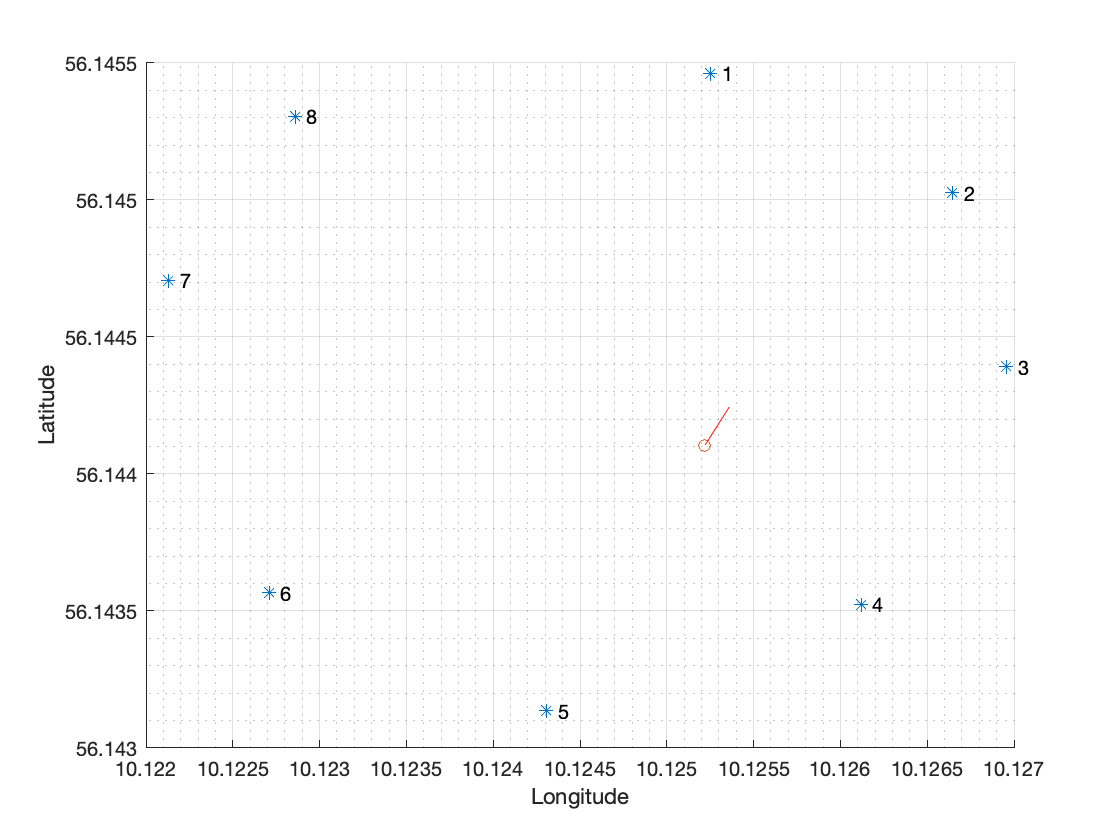

boat_unit_vector =    56.1442   10.1254


boat = [gps_postion boat_dir];
boat_unit_vector = [0.0002*cosd(boat_dir) 0.0002*sind(boat_dir)];
boat_unit_vector = boat_unit_vector + gps_postion;
gps_targets = [ 56.145462, 10.125252;
                56.145026, 10.126647;
                56.144392, 10.126958;
                56.143525, 10.126121;
                56.143136, 10.124308;
                56.143566, 10.122709;
                56.144708, 10.122130;
                56.145306, 10.122860; ];

clf;
draw_boat_target(boat,gps_targets)

calcuculating the angle: 

results = zeros(length(gps_targets),4);
length_n_angle = zeros(length(gps_targets),2);
for i = 1:length(gps_targets)
    
    results(i,1) = distance_between_coordinates_degree(boat(1:2), gps_targets(i,:));
    
    results(i,2) = cal_angle(boat, gps_targets(i,:));
    
    temp = results(i,1)*exp(1)^(j*deg2rad(results(i,2)));
    
    results(i,3:4) = [real(temp)+boat(1) imag(temp)+boat(2)]; 
    
    length_n_angle(i,1) = distrance_between_coordinates(boat(1:2), gps_targets(i,:));
    length_n_angle(i,2) = cal_angle_to_target(boat,gps_targets(i,:));
end

results

results =     0.0014    1.3509   56.1455   10.1253
    0.0017   57.1614   56.1450   10.1266
    0.0018   80.6232   56.1444   10.1270
    0.0011  122.7706   56.1435   10.1261
    0.0013 -136.7357   56.1431   10.1243
    0.0026 -102.1150   56.1436   10.1227
    0.0031  -78.9578   56.1447   10.1221
    0.0026  -63.0285   56.1453   10.1229


length_n_angle

length_n_angle =   151.1085  -43.6491
  135.5893   12.1614
  112.6618   35.6232
   85.4829   77.7706
  121.8802  178.2643
  167.2250 -147.1150
  203.4721 -123.9578
  198.5017 -108.0285



legends = [];
clf;
for i = 1:length(gps_targets)
    draw_line(flip(results(i,3:4)),flip(boat(1:2)));
    
    legends = [legends ; sprintf( ...
        "tgt. %d, dis. %3.2f m, trig angle: %3.2f ang from dir %3.2f", ...
        i, ...
        length_n_angle(i,1), ...
        results(i,2), ...
        length_n_angle(i,2))];
    
    %text(results(i,4),results(i,3),' ' +sprintf(" %d",i))
end
hold on 
draw_boat_target(boat, gps_targets);

boat_unit_vector =    56.1442   10.1254


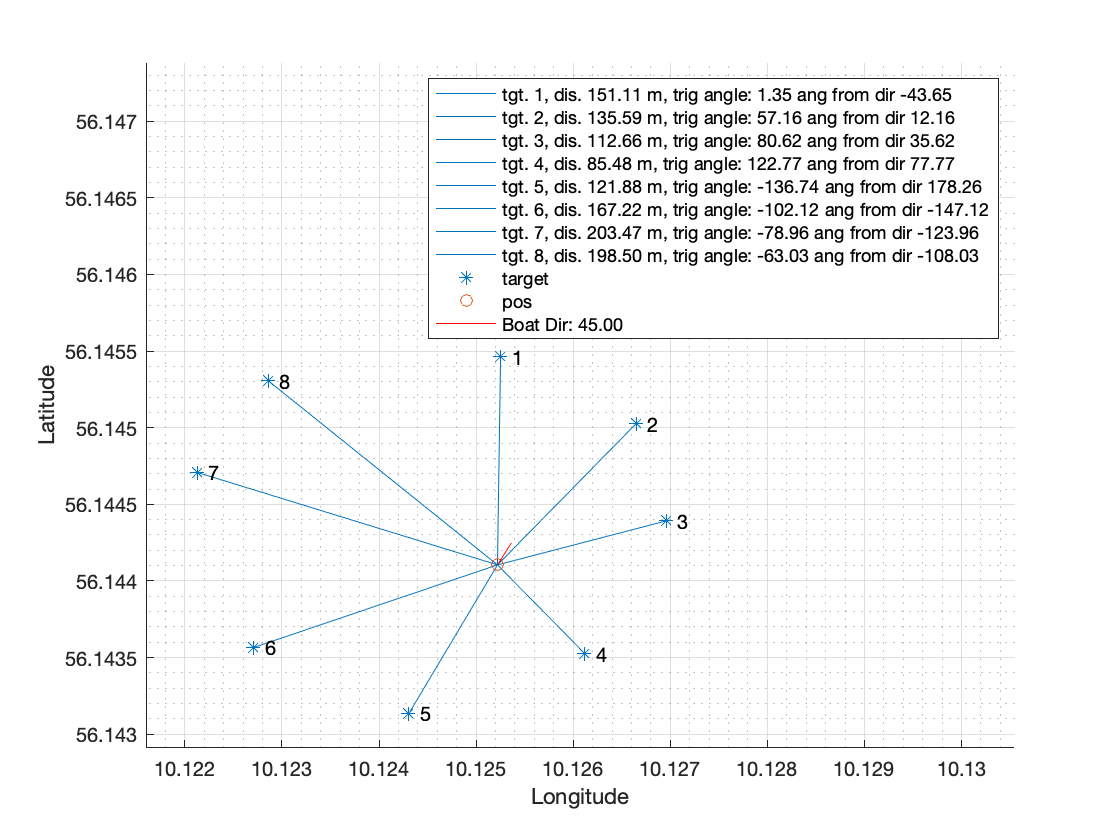

legend(legends(1) ...
    ,legends(2) ...
    ,legends(3) ...
    ,legends(4) ...
    ,legends(5) ...
    ,legends(6) ...
    ,legends(7) ...
    ,legends(8) ...
    ,'target' ...
    ,'pos' ...
    , sprintf("Boat Dir: %3.2f",boat(3))) 

xlim([10.12160 10.13054])
ylim([56.14291 56.14738])



disp(sprintf("new way lati %f",length_of_latitude(56)))

new way lati 111341.948121


disp(sprintf("new way longi: %f",length_of_longitude(56)))

new way longi: 62392.617519


disp(sprintf("old way lati: %f", latitude_degree_meter(56)))

old way lati: 111218.583439


disp(sprintf("old way longi: %f",longitude_degree_meter()))

old way longi: 17717.047222


disp(sprintf("%f",earth_radius(56)))

6372355.434495


earth_radius(56)/360

ans = 1.7701e+04

# angle functions

function [course_adjustment] = cal_angle_to_target(boat, target)
    % calculates the angle to the target

    
    target_angle_degrees_tri = cal_angle(boat,target);
    
    %Turn into compass  degrees
    target_angle_degres_map = 360-mod((target_angle_degrees_tri-90),360);
    
    % find the inital diffrence between the angles
    non_finsihed = boat(3) - target_angle_degres_map;
    
    %  Figure out if the boat is trying to turn the long way around
    if non_finsihed > 180 
        final = non_finsihed - 360;
    elseif non_finsihed < -180
        final = non_finsihed + 360;
    else
        final = non_finsihed;
    end
    course_adjustment = final;
end

function [vector_angle] = cal_angle(boat, target)
    %localise the target 
        d_lat = target(1) - boat(1);
        d_lon = target(2) - boat(2);
        % Find the radian angle
        angle_radian = atan2(d_lon, d_lat);
        
        % Convert to degrees
        rad_deg_realtion = 360/(2*pi);
        vector_angle = angle_radian * rad_deg_realtion;
end

# Length functions

function R = earth_radius(latitude)
    e_r = 6378.137 * 1000; % m % radius at the equator
    p_r = 6356.752 * 1000; % m % radius at poles 
    
    term1 = abs((e_r^2 * cos(latitude))^2 + (p_r^2 * sin(latitude))^2);
    term2 = abs((e_r * cos(latitude))^2 + (p_r * sin(latitude))^2);
    
    R = sqrt(term1/term2);
end
function C = earth_cicumfrence(R)
    C = 2 * R * pi;

end

function lat_m = latitude_degree_meter(latitude)
    R = earth_radius(latitude);
    C = earth_cicumfrence(R);
    lat_m = C/360;
    
end

function lon_m = longitude_degree_meter()
    
    lon_m = (6378.137 * 1000)/360; 
    
end
function lon_m = length_of_latitude(latitude)
    lon_m = 111132.92 - 559.82 * cosd(2*latitude)+1.175*cos(4*latitude)-0.0023*cos(6*latitude);
end
function lon_m = length_of_longitude(latitude)
    lon_m = 111412.84*cosd(latitude) - 93.5 * cosd(3*latitude)+0.118*cos(5*latitude);
end

function D = distance_between_coordinates_degree(pos, tar)
    delta_latitude = tar(1) - pos(1);
    delta_longitude = tar(2) - pos(2);
    
    D = sqrt(delta_latitude^2 + delta_longitude^2);
end

function D = distrance_between_coordinates(pos, tar)
    delta_latitude = tar(1) - pos(1);
    delta_longitude = tar(2) - pos(2);
    
    %lat_m = latitude_degree_meter(pos(1));
    lat_m = length_of_latitude(pos(1));
    delta_latitude_meter = delta_latitude * lat_m; 
    %lon_m = longitude_degree_meter();
    lon_m = length_of_longitude(pos(1));
    delta_longitude_meter = delta_longitude * lon_m;
    
    D = sqrt(delta_latitude_meter^2 + delta_longitude_meter^2);
end


# Draw methoed

function draw_boat_target(boat,targets)

    boat_unit_vector = [0.0002*cosd(boat(3)) 0.0002*sind(boat(3))];
    boat_unit_vector = boat_unit_vector + boat(1:2)
    scatter(targets(:,2), targets(:,1),'*')
    hold on
    scatter(boat(2),boat(1),'o')
    hold on
    draw_line(flip(boat_unit_vector),flip(boat(1:2)),'r');
    hold on
    for i = 1:length(targets)
        text(targets(i,2),targets(i,1),' ' +sprintf(" %d",i));
    end
    ylabel('Latitude')
    xlabel('Longitude')
    grid on
    grid minor
    hold off
    
end